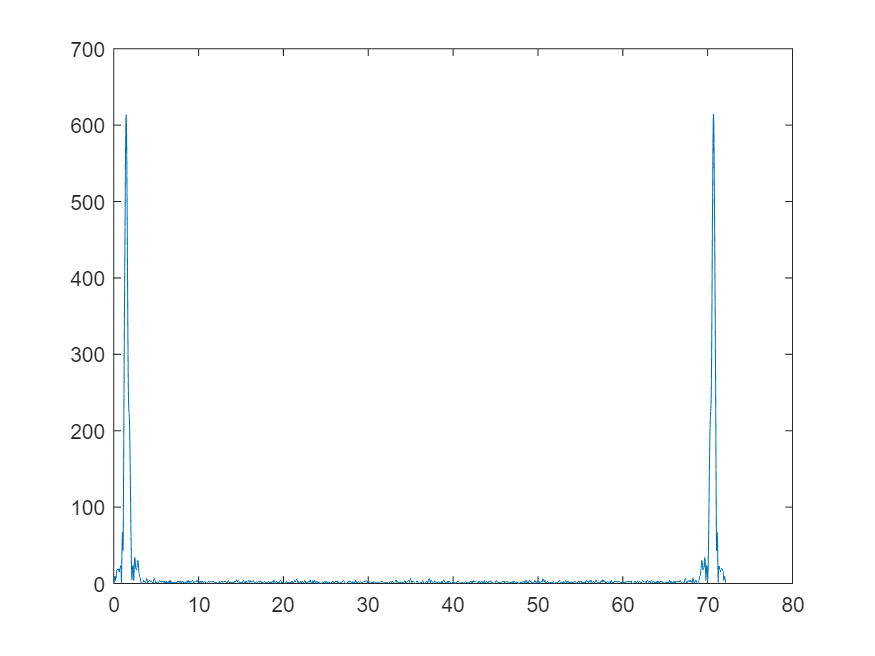

clc; clear all;
%显示光谱信息
format long
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
spectrum_intensity = (spectrum{:,2})';
%disp("全部光谱信息");
plot(spectrum_frequency,spectrum_intensity)

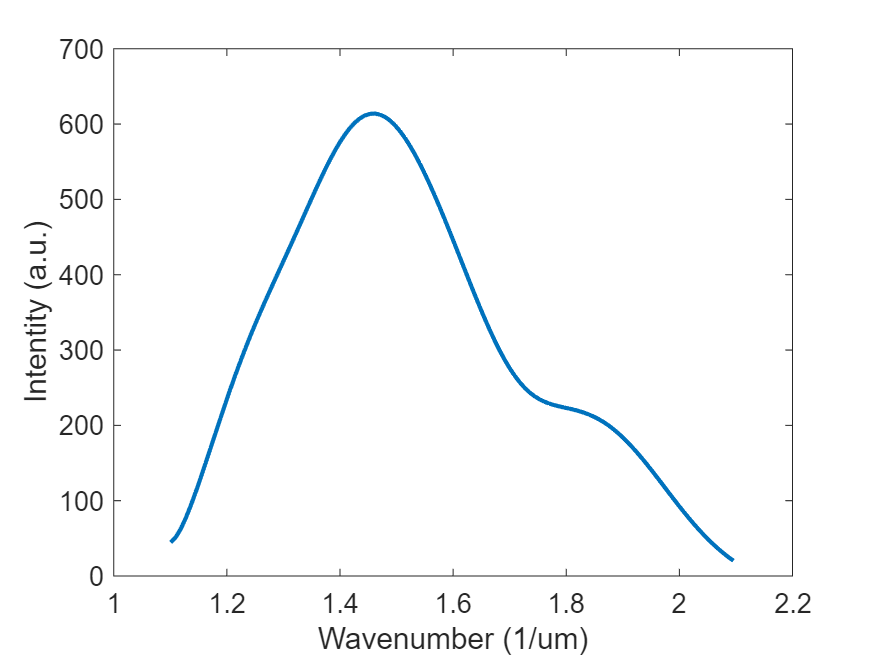

%找出探测器对应的光谱，这里假设是1.1-2.1
[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
%disp("需要的光谱信息");
plot(spectrum_frequency,spectrum_intensity,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;


%色散相位
%加入色散
%色散公式
lEpsilon = 20; %单位为微米
lambda = 1./spectrum_frequency;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
Phase = 4*pi*(index-1).*spectrum_frequency*lEpsilon+30*spectrum_frequency.^3;
plot(spectrum_frequency,Phase,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Phase (rad)')
ax = gca;
ax.FontSize = 13;
%拟合
p = polyfit(spectrum_frequency,Phase,1)

p = 	1.0e+00 *

  369.6606 -248.8693


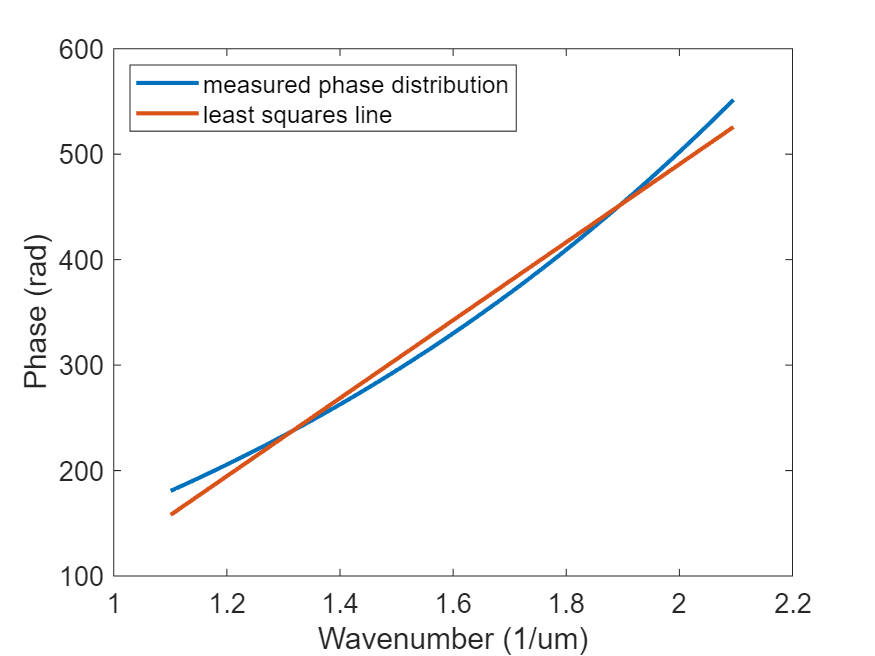

phase_fit = p(1)*spectrum_frequency+p(2);
hold on 
plot(spectrum_frequency,phase_fit,'LineWidth',2);
hold off
legend('measured phase distribution','least squares line','Location','northwest')

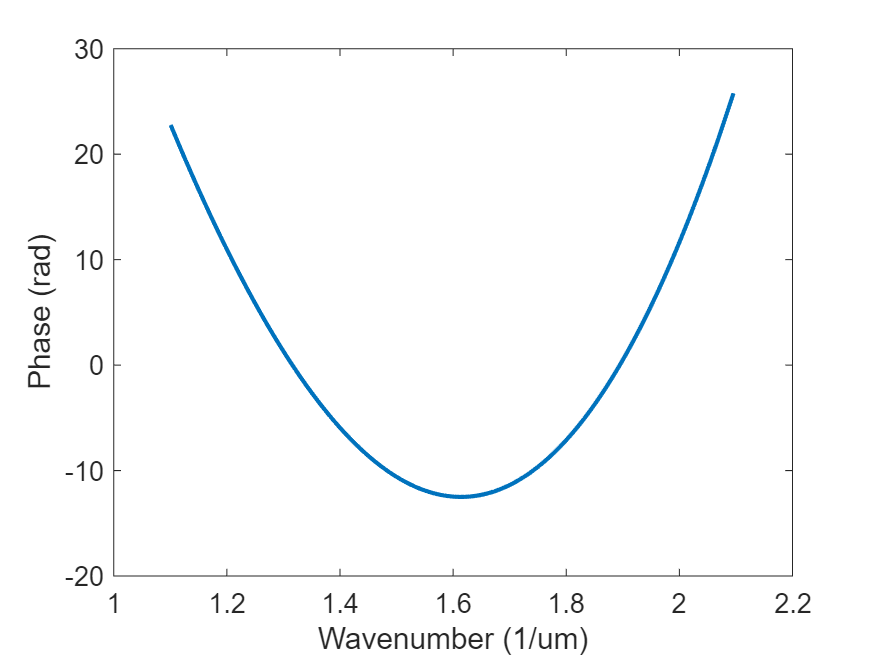

%非线性相位
plot(spectrum_frequency,Phase-phase_fit,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Phase (rad)')
ax = gca;
ax.FontSize = 13;

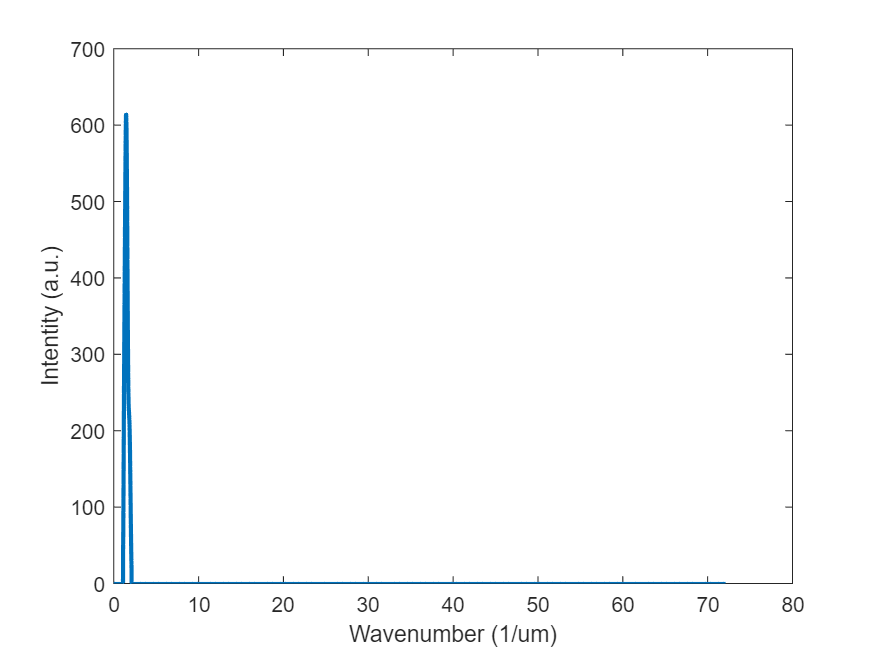


Phase2 = Phase-phase_fit;
Phase3 = phase_fit;
flag = 1;
%傅里叶逆变换求z0
%正频域部分信号F(sigma)。
sigma = (spectrum{:,1})';
windowf = zeros(1,numel(sigma));
windowf(indix_min:indix_max) = 1;
[I_sigma,n] = sigmult(spectrum_intensity,indix_min:indix_max,windowf,1:length(windowf));
[P_sigma,~] = sigmult(Phase,indix_min:indix_max,windowf,1:length(windowf));
F_sigma = I_sigma.*exp(1i*P_sigma);
plot(sigma,I_sigma,'LineWidth',2);
xlabel('Wavenumber (1/um)') 
ylabel('Intentity (a.u.)')

%计算加权平均波长
%lambdaA：加权平均波长
%powerTotal：总的波数振幅相加
%-----------------------------------
I_sigma1 = spectrum_intensity;
sigma1 = sigma(indix_min:indix_max);
powerTotal = sum(I_sigma1);
power = sum(I_sigma1.*sigma1);
lambdaA = powerTotal/power

lambdaA =    0.656653661474092


%-----------------------------------

% %逆傅里叶变换
% Nifft = 2^20;
% interference_signal1 = ifft(F_sigma,Nifft);
% deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
% deltaZ = 1/(2*Nifft*deltaSigma);
% zData = (1:Nifft)*deltaZ;
% intensity = abs(interference_signal1);
% phase = angle(interference_signal1);

%-----------------------------------
%逆傅里叶变换
Nifft = 2^20;
interference_signal1 = ifft(F_sigma,Nifft);
deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
deltaZ = 1/(2*Nifft*deltaSigma);
zData = (1:Nifft)*deltaZ;
intensity = abs(interference_signal1);
phase = angle(interference_signal1);
[~,index3]= max(intensity);
za1 = zData(index3);
%-----------------------------------
[~,indexend] = min(abs(zData-(za1+0.5)));
[~,indexstart] = min(abs(zData-(za1-0.5)));
unwrapZend = zData(indexend);
unwrapZ_1 = zData(indexstart);
unwrapN1 = index3;
unwrapNe = find(zData==unwrapZend);
unwrapN_1 = find(zData==unwrapZ_1);
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index3);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    if n>1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
    else
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
a1 = p(1)

a1 =      3.696606080716928e+02


a0 = wrapToPi(p(2))

a0 =    2.458097403511363


if flag==1
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N-zData(end)
za1 = za1-zData(end)
zData = zData - zData(end);
else
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N
za1
end

zp1 =  -25.670595016919577


za1 =  -25.697807240625000


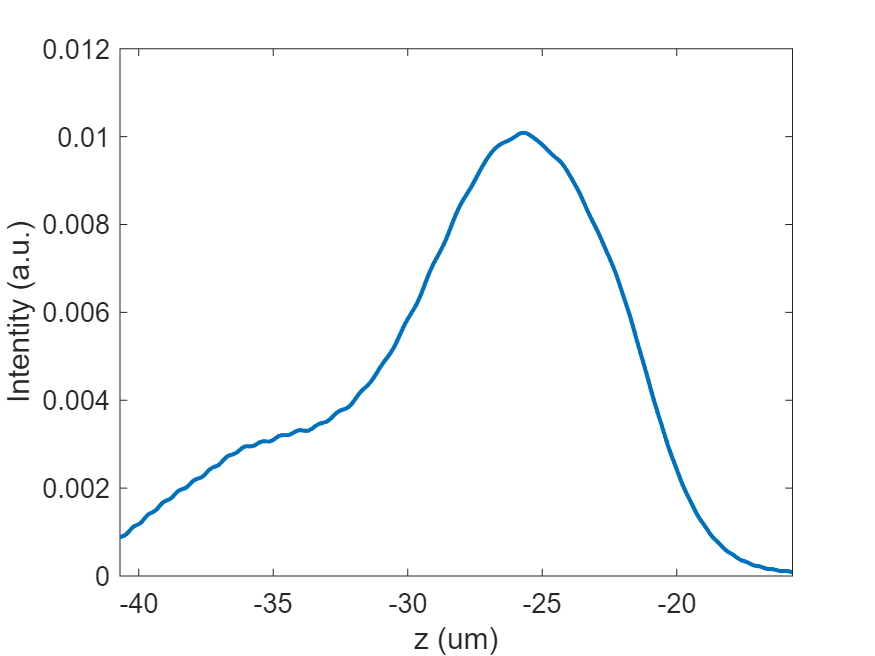

plot(zData,intensity,'LineWidth',2);
xlabel('z (um)') 
ylabel('Intentity (a.u.)')
ax = gca;
ax.FontSize = 13;
xlim([zData(index3)-15 zData(index3)+10]);

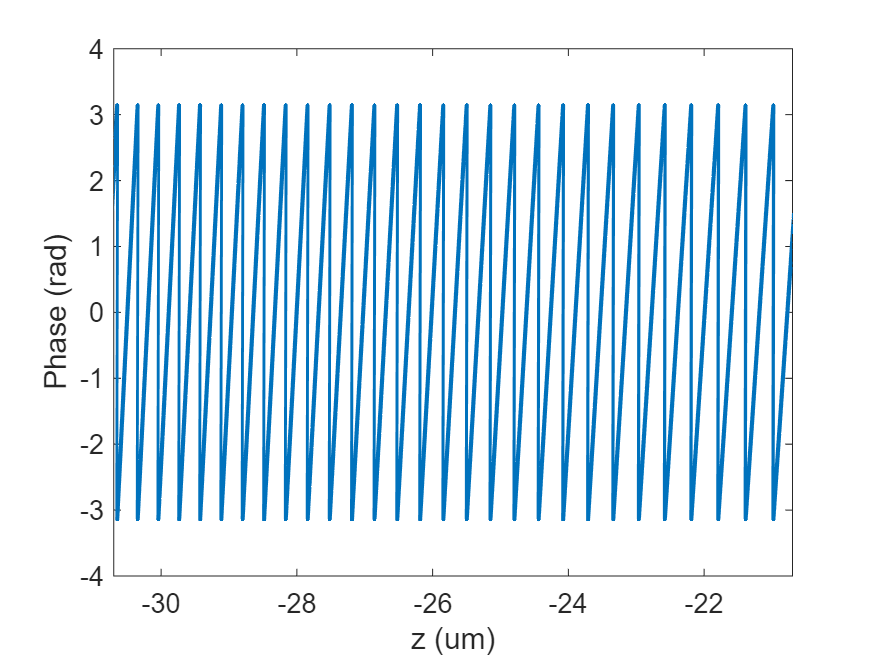

plot(zData,phase,'LineWidth',2);
xlabel('z (um)') 
ylabel('Phase (rad)');
xlim([zData(index3)-5 zData(index3)+5]);
ax = gca;
ax.FontSize = 13;

function [y,n] = sigmult(x1,n1,x2,n2)
%implements y(n) = x1(n) * x2(n);
%-----------------------------------
%[y,n]=siggadd(x1,n1,x2,n2)
%x1=first sequence over n1
%x2=first sequence over n1
n = min(min(n1),min(n2)):max(max(n1),max(n2));
y1 = zeros(1,length(n));
y2 = y1;
y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;
y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;
y=y1.*y2;
end